# Running Python Code With MATLAB

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

There are many programming languages in the world and they all have different features. You may have occasions where you want to reuse existing code, call on functionality from another language, or collaborate with someone who prefers to work in a different language than you. It is quite possible to use multiple programming languages together, although in some cases the interface may be awkward if the underlying structures are different. This script introduces a Live Task that can be used as a graphical user interface to run Python code from MATLAB.

This script is intended to be run one section at a time, in order. If you choose to skip around, you may encounter errors.

## Getting ready

### Step 1: Check your MATLAB version 

Including user-authored Live Tasks is only supported starting in R2022a. What version are you running?

releaseInfo = matlabRelease;
str = "This is release " + releaseInfo.Release + ",";
if isMATLABReleaseOlderThan("R2022a")
    disp(str + " so it will not run this example.")
else
    disp(str + " so you can proceed with this script.")
end

### Step 2: Check your Python version

You must have Python installed, and it must be a [supported version of Python](https://www.mathworks.com/support/requirements/python-compatibility.html) for your MATLAB version. For R2022a, you need to use 2.7, 3.8, or 3.9. What version are you using?

CheckPythonVersion

If you do not have a supported version of Python installed, follow the instructions in the [documentation to install and select](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html) a supported version. If you have a supported version of Python installed, but it is not on your MATLAB path, you will need to add it using `addpath`

## Identify Code to Run

Here is a few lines of Python code to compute tax due.

You cannot copy this to a command line and run it, but the Run Python Code live script will build the necessary wrapping code, although you may need to specify what values are being passed in from MATLAB variables.

## Investigate the Run Python Code Live Task

 Insert the Live Task below by going to the **Live Editor** tab, selecting the **Task** drop-down in the **Code **section of the toolstrip, and then selecting **Run Python Code** from among the **External Language Interfaces**.

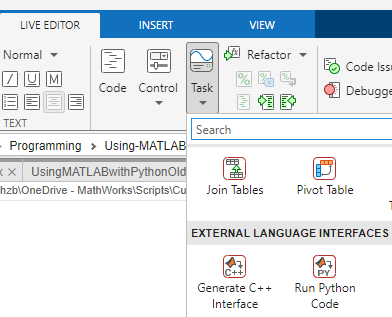

Alternatively, you may simply type `python` in a code block, and the autocomplete feature will suggest the appropriate task:

In the top right corner of the live task there is a run button () that you can use to run the current section.

If you select the breadcrumbs in the top right corner, you can bring up a variety of options including "Remove Task" and, once you have added some Python code, the option to select whether you see only the controls, both the controls and the code or only the generated code. 

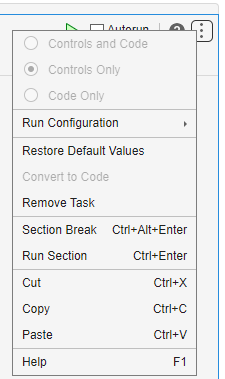

Expanding the Output options section allows you to limit the set of variables that will be returned. While this is not necessary in a small testcase, it can be very helpful to avoid being overwhelmed by local Python values in more complex cases. 

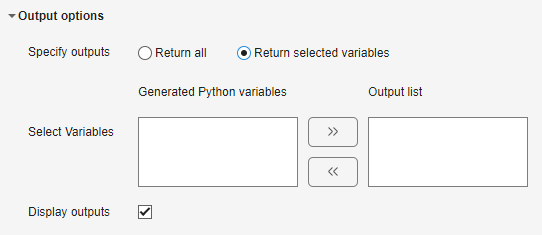

## Try Running Python Code

### Run Python statements

  **Try**. Test your ability to use the Run Python Code Live Task.

- Set up variables to use as input.

dollars = "$38.12";
percent = "6.23%";

 **Warning **

While you can always view the contents of the MATLAB workspace, the Python workspace is separate and opaque to you. The first time you run this Live Task, it will add variables to your Python workspace. For future iterations, the original values you passed in will exist so unless you change the name of the variable you are passing in, the new values will not be picked up by the Live Task for inclusion in the Python workspace. 

When you restart MATLAB you should end up with a new Python workspace as well. Similarly, subsequent iterations of the Live Task may result in changing the variable name of the output from something like `tax` to `tax2` or `tax3`, etc. 

        2. Copy the sample Python code generated here into the Live Task and unfold the "Show code". Do not run it yet.

If you want to use more elegant output formatting, that is available depending on your Python version:

        3. Open the Output options section to control the output. Select "Return selected variables" and choose the variable "tax". Then observe the generated code. What has changed?

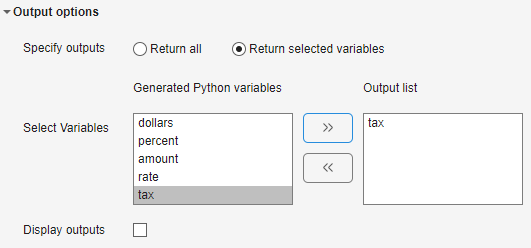

        4. Convert the Live Task to its generated code. 

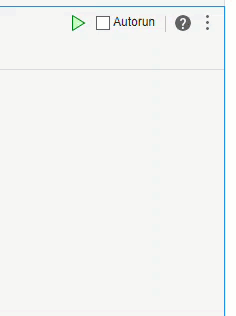

Now run the result. Change the values of `dollars` and `percent` above, and rerun the code. Does it work as you expect? If not, please run the check the follows.

C = who();
idxs = find(contains(string(C),"pycode"));
if numel(idxs) > 0
    testStr = eval(C{idxs(end)});
    CheckMyCode(testStr)
else
    disp("You do not have any Python code defined by the Live Task. Please try again.")
end

5. Check that tax is a variable in the MATLAB Workspace. What value does it contain? 

### Run Python scripts

If you have a Python script, the Run Python Code Live Task also supports running scripts. To test this capability, there is a Python script in this folder called `helloworld.py` that takes one input variable called `name`. First, define a value for `name`:

name = "Team";

  **Try. Use the Run Python Code Live Task to run **`helloworld.py`**.**

        1. In the code box, below, insert the Run Python Code Live Task. 

        2. Select "Python script file" in the Run Python Code Live Task.

        3. Use your file selector to select the `helloworld.py` file in the `FunctionLibrary` folder. You can find the full path using the command `which`

        4. Add the input variable `name` from the Workspace with Python variable name `name`.

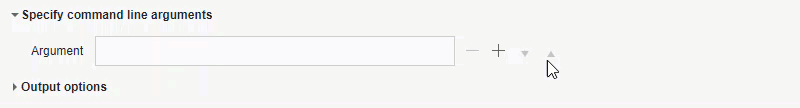

        5. Run this section. 

## Creating a Simple Weather Display

Now that you have installed and tested the Run Python Code Live Task, let's use it to help build a script that will check the current weather and short-term forecast and display the results. 

edit CheckingTheWeather.mlx

## Further Explorations

If this has whet your appetite, it is possible to go much farther with integrating code back and forth between [MATLAB and Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html). 

- Documentation on [calling Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html)

- Documentation on [calling MATLAB from Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)

- A deep learning example for [speech recognition](https://github.com/matlab-deep-learning/coexecution_speech_command)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

function CheckMyCode(str)
flag = 1;
outStr = "[tax] = pyrun(pycode, ..." + newline + ...
    " [ ""tax"" ], ""dollars"", dollars, ""percent"", percent)";
if ~(any(contains(str,"pyDollars = dollars")) && any(contains(str,"pyPercent = percent")))
    disp("You are missing the identification of dollars and percent as variables to be passed.")
    flag = 0;
end    
if ~(any(contains(str,"amount = float(pyDollars.lstrip(""$""))")) && any(contains(str,"rate = float(pyPercent.rstrip(""%""))/100")))
    disp("You are missing the definitions of amount and rate.")
    flag = 0;
end
if ~any(contains(str,"tax = amount*rate"))
    disp("You are missing the computation of the tax.")
    flag = 0;
end
if flag == 1
    disp("Your Python code looks correct, but you may have incorrect pyrun code.")
    disp("It should say: ")
    disp(outStr)
end
end
